s = [0:.001:15];
coeff = coeffs;


 %calculate switching points in s   
    if any(s < 0)
        ex = MException('Path:notDefined',"Path only defined for positive s.");
        throw(ex)
    end
    
    s_switch = [0, cumsum(sqrt(diff(wpx2).^2+diff(wpy2).^2))];
    splineIdx = zeros(length(s),1);
    
    for i = 1:length(s)
        idx = find((s_switch <= s(i)) == 0,1);
        if length(idx) == 0
            idx = length(s_switch);
        end
        splineIdx(i,1) = idx-1;
    end
    if(coeff(1:2, splineIdx) == zeros(2,1))
      %%linear with dx=0, without analytical description
      dy = s-s_switch(splineIdx)
      dx = 0
    else
      %%linear with valid analytical description
      dx = cos(atan(coeff(2,splineIdx))).*(s-s_switch(splineIdx));
      dy = sin(atan(coeff(2,splineIdx))).*(s-s_switch(splineIdx)); 
    end
    x = wpx2(splineIdx) + dx

x =    -2.0000   -1.9995   -1.9990   -1.9985   -1.9979   -1.9974   -1.9969   -1.9964   -1.9959   -1.9954   -1.9949   -1.9943   -1.9938   -1.9933   -1.9928   -1.9923   -1.9918   -1.9913   -1.9907   -1.9902   -1.9897   -1.9892   -1.9887   -1.9882   -1.9877   -1.9871   -1.9866   -1.9861   -1.9856   -1.9851   -1.9846   -1.9841   -1.9835   -1.9830   -1.9825   -1.9820   -1.9815   -1.9810   -1.9804   -1.9799   -1.9794   -1.9789   -1.9784   -1.9779   -1.9774   -1.9768   -1.9763   -1.9758   -1.9753   -1.9748


    y = wpy2(splineIdx) + dy

y =          0    0.0009    0.0017    0.0026    0.0034    0.0043    0.0051    0.0060    0.0069    0.0077    0.0086    0.0094    0.0103    0.0111    0.0120    0.0129    0.0137    0.0146    0.0154    0.0163    0.0171    0.0180    0.0189    0.0197    0.0206    0.0214    0.0223    0.0232    0.0240    0.0249    0.0257    0.0266    0.0274    0.0283    0.0292    0.0300    0.0309    0.0317    0.0326    0.0334    0.0343    0.0352    0.0360    0.0369    0.0377    0.0386    0.0394    0.0403    0.0412    0.0420


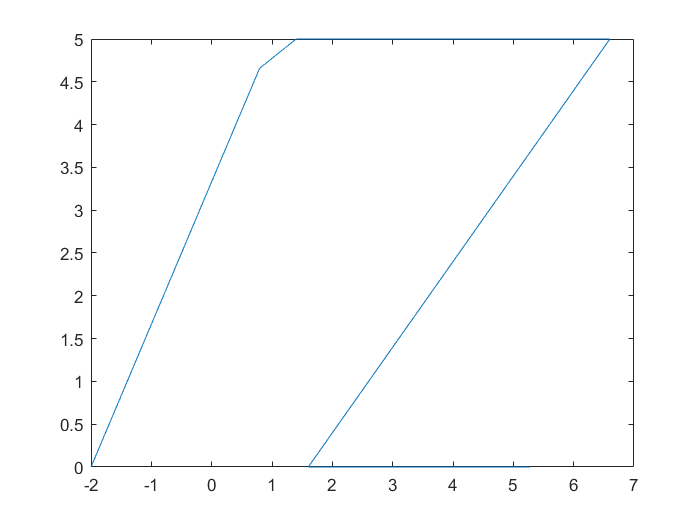


plot(x,y)